% Define file path (Update with your actual file location)
filepath = "tracking_data.csv"

filepath = "tracking_data.csv"

% Read the CSV file
data = readtable(filepath); % Use readmatrix(filePath) if no headers

% Display first few rows to check structure
disp(data(1:5, :));

     Var1      Var2    Var3    Var4    Var5
    _______    ____    ____    ____    ____

    0.27829    2.19    7.19    1.55    7.15
    0.29755    2.19    7.19    1.55    7.15
    0.31377    2.19    7.19    1.55    7.15
    0.34902    2.19    7.19    1.55    7.15
    0.37254    2.19    7.19    1.55    7.15




% Extract data (modify column indices if necessary) 
time = data{:,1};
x1 = data{:, 2}; % First dataset X values
y1 = data{:, 3}; % First dataset Y values
x2 = data{:, 4}; % Second dataset X values
y2 = data{:, 5}; % Second dataset Y values

% Generate sample indices (assuming number of rows in data)
numSamples = 1:length(x1); % X-axis as sample index (time or sample number) 

% Compute Percentage Error
percentageError = abs((x1 - x2) ./ x2) * 100; % Element-wise percentage error

% Display results
fprintf('Mean Percentage Error: %.4f%%\n', mean(percentageError));

Mean Percentage Error: 30.2355%


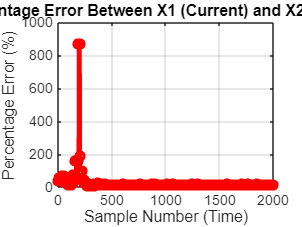


% Plot Percentage Error over time
figure;
plot(1:length(x1), percentageError, '-o', 'LineWidth', 2, 'MarkerSize', 5, 'Color', 'r');
xlabel('Sample Number (Time)');
ylabel('Percentage Error (%)');
title('Percentage Error Between X1 (Current) and X2 (Desired)');
grid on 



% Compute Percentage Error 
Error_y = abs((y1 - y2)); % Element-wise percentage error
percentageError = abs((y1 - y2) ./ y2) * 100; % Element-wise percentage error

fprintf('Mean Percentage Error: %.4f%%\n', mean(percentageError));

Mean Percentage Error: 3.1606%


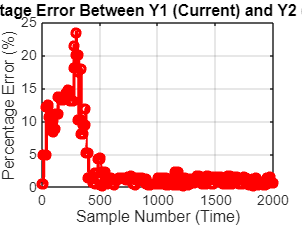


% Plot Percentage Error over time
figure;
plot(1:length(x1), percentageError, '-o', 'LineWidth', 2, 'MarkerSize', 5, 'Color', 'r');
xlabel('Sample Number (Time)');
ylabel('Percentage Error (%)');
title('Percentage Error Between Y1 (Current) and Y2 (Desired)');
grid on

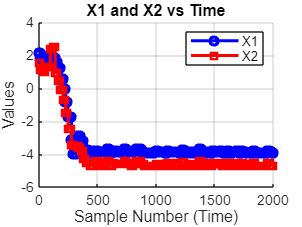


% Plot X1 and Y1
figure;
hold on;
plot(numSamples, x1, '-o', 'LineWidth', 2, 'MarkerSize', 5, 'Color', 'b', 'DisplayName', 'X1');
plot(numSamples, x2, '-s', 'LineWidth', 2, 'MarkerSize', 5, 'Color', 'r', 'DisplayName', 'X2');
xlabel('Sample Number (Time)');
ylabel('Values');
title('X1 and X2 vs Time');
legend show;
grid on;
hold off;

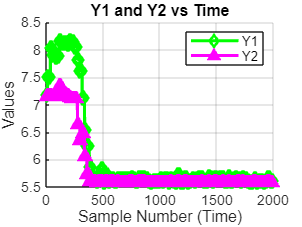


% Plot X2 and Y2
figure;
hold on;
plot(numSamples, y1, '-d', 'LineWidth', 2, 'MarkerSize', 5, 'Color', 'g', 'DisplayName', 'Y1');
plot(numSamples, y2, '-^', 'LineWidth', 2, 'MarkerSize', 5, 'Color', 'm', 'DisplayName', 'Y2');
xlabel('Sample Number (Time)');
ylabel('Values');
title('Y1 and Y2 vs Time');
legend show;
grid on;
hold off;  

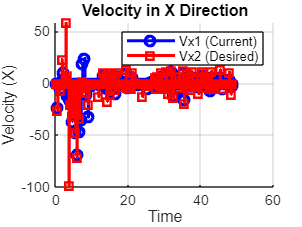


% Compute time differences
dt = diff(time); % time step differences

% Compute velocities for each axis (difference in position / difference in time)
vx1 = diff(x1) ./ dt; % Velocity in X for current
vy1 = diff(y1) ./ dt; % Velocity in Y for current
vx2 = diff(x2) ./ dt; % Velocity in X for desired
vy2 = diff(y2) ./ dt; % Velocity in Y for desired

% Midpoint time values for velocity plots (since diff reduces vector size by 1)
time_mid = time(1:end-1) + dt / 2; 

% Plot X Velocity Comparison
figure;
hold on;
plot(time_mid, vx1, '-o', 'LineWidth', 2, 'Color', 'b', 'DisplayName', 'Vx1 (Current)');
plot(time_mid, vx2, '-s', 'LineWidth', 2, 'Color', 'r', 'DisplayName', 'Vx2 (Desired)');
xlabel('Time');
ylabel('Velocity (X)');
title('Velocity in X Direction');
legend show;
grid on;
hold off;

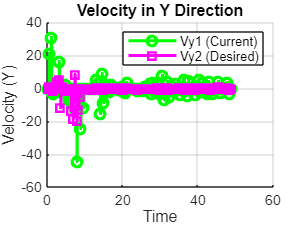


% Plot Y Velocity Comparison
figure;
hold on;
plot(time_mid, vy1, '-o', 'LineWidth', 2, 'Color', 'g', 'DisplayName', 'Vy1 (Current)');
plot(time_mid, vy2, '-s', 'LineWidth', 2, 'Color', 'm', 'DisplayName', 'Vy2 (Desired)');
xlabel('Time');
ylabel('Velocity (Y)');
title('Velocity in Y Direction');
legend show;
grid on;
hold off;